# Homework 4

## Problem 13.9: Determine the mean, ACVS and stationarity of a random process

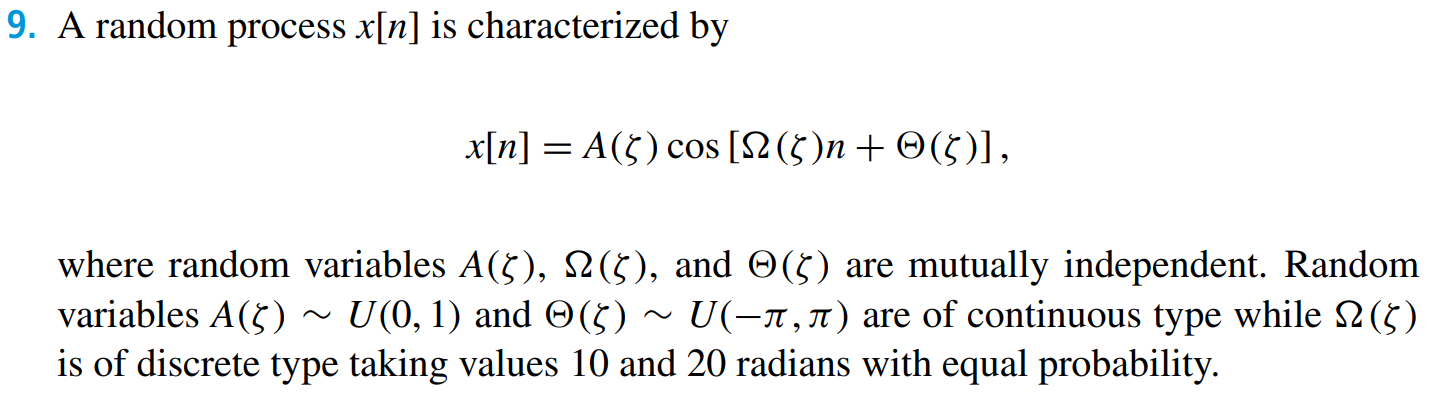

### [✔] a) Determine the mean sequence $m_x \left\lbrack n\right\rbrack$

We need to compute:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$$


Since the three random variables are independent then we can write:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \;\cos \left(\Omega n+\Theta \right)\right\rbrack$$


We know that $E\left\lbrack A\right\rbrack =\frac{1}{2}$ since $A\sim U\left(0,1\right)$.

Computing the expression $E\left\lbrack \mathrm{sin}\left(\Theta \right)\right\rbrack$ requires a bit of an explanation. 

Suppose we want to compute $E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$ where $\Theta \sim U\left(-\pi ,\pi \right)$. Let us pick one frequency $\omega$ (realise one value of $\Omega$). Then let us pick a lot of realisations of $\Theta$. Now if we plot the function $\mathrm{cos}\left(\omega \;n+\theta \right)$ for different values of $\theta$ then we will see something like this:

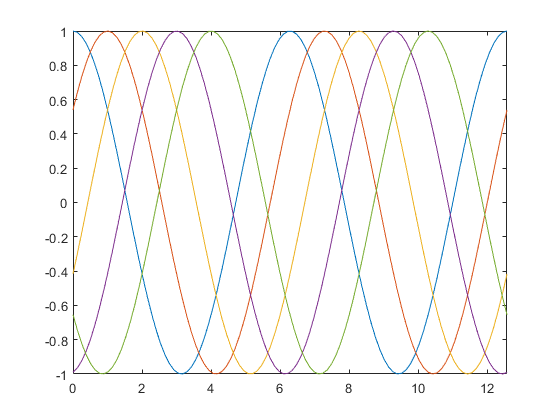

n = linspace(0, 4*pi);
plot(n, cos(n), n, cos(n-1), n, cos(n-2), n, cos(n-3), n, cos(n-4));
xlim([0, 4*pi]);

If we plot hundreds of cosine functions shifted slightly, we get a large blob of points from -1 to 1. For this reason, the quality $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack$ will be zero because the mean value is 0. Formally, we can write:


$$E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } f_{\Theta } \left(\Theta \right)\cdot \mathrm{cos}\left(\Omega n+\Theta \right)\;d\Theta =\frac{1}{2\pi }\int_{-\pi }^{\pi } \mathrm{cos}\left(\Omega n+\Theta \right)\;d\Theta$$


So we are integrating cosine function over $2\pi$ which is zero.

In signal processing, we like to add random shifts ala $\Theta \sim U\left(0,2\pi \right)$ to avoid that the expected value or the mean value becomes dependent on time. 

Alternatively, we can use

Using the rule $\mathrm{cos}\left(\alpha +\beta \right)=\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)-\mathrm{sin}\left(\alpha \right)\mathrm{sin}\left(\beta \right)$, we rewrite the expression to:


$$\begin{array}{l}
E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\left(\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)-\sin \left(\Omega n\right)\sin \left(\Theta \right)\right)\right\rbrack \\
E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)-A\;\sin \left(\Omega n\right)\sin \left(\Theta \right)\right\rbrack 
\end{array}$$


At this point, we need to employ some expection rules to decompose the expression.

Let $X$ and $Y$ be two random variables and $a$ and $b$ be two constants. Following expectation identities apply:

- $E\left\lbrack a\right\rbrack =a$               e.g. $E\left(42\right)=42$

- $E\left\lbrack a\;X\right\rbrack =a\;E\left\lbrack X\right\rbrack$   e.g. if you multiply every value by 2, the expectation doubles

- $E\left\lbrack a\pm X\right\rbrack =a\pm E\left\lbrack X\right\rbrack$ e.g. if you add 42 to every case, the expectation increases by 42

- 
$$E\left\lbrack X+Y\right\rbrack =E\left\lbrack X\right\rbrack +E\left\lbrack Y\right\rbrack$$


- If $X$ and $Y$ are independent, then $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

- 
$$E\left\lbrack a\pm \mathrm{bX}\right\rbrack =a\pm E\left\lbrack b\;X\right\rbrack =a\pm b\;E\left\lbrack X\right\rbrack$$


- 
$$E\left\lbrack b\left(a\pm \textrm{X}\right)\right\rbrack =b\;E\left\lbrack a\pm \textrm{X}\right\rbrack =b\left(a\pm E\left\lbrack X\right\rbrack \right)$$


Use rule 4:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\cos \left(\Omega n\right)\;\cos \left(\Theta \right)\right\rbrack -E\left\lbrack A\;\sin \left(\Omega n\right)\sin \left(\Theta \right)\right\rbrack$$


Use rule 5 multiple times:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \mathrm{cos}\left(\Omega n\right)\right\rbrack E\left\lbrack \mathrm{cos}\left(\Theta \right)\right\rbrack -E\left\lbrack A\right\rbrack E\left\lbrack \mathrm{sin}\left(\Omega n\right)\right\rbrack E\left\lbrack \mathrm{sin}\left(\Theta \right)\right\rbrack$$


**But how can we continue from here?**

We know that $\Theta \sim U\left(-\pi ,\pi \right)$ so $E\left\lbrack \Theta \right\rbrack =\frac{\pi +\left(-\pi \right)}{2}=\frac{0}{2}=0$

### b) Determine the ACVS $c_X \left\lbrack m,n\right\rbrack$

### c) Comment on the stationarity of the random process

## Problem 13.13: MSE objective function

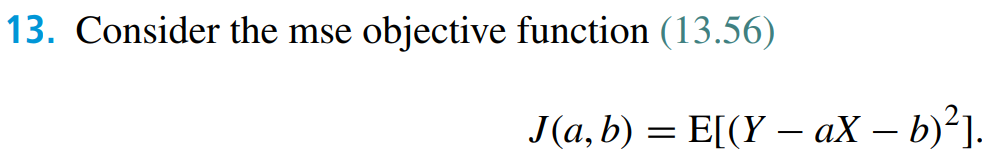

### a) Express the objective function in terms of its parameters

### b) Using partial derivatives to determine the values of parameters

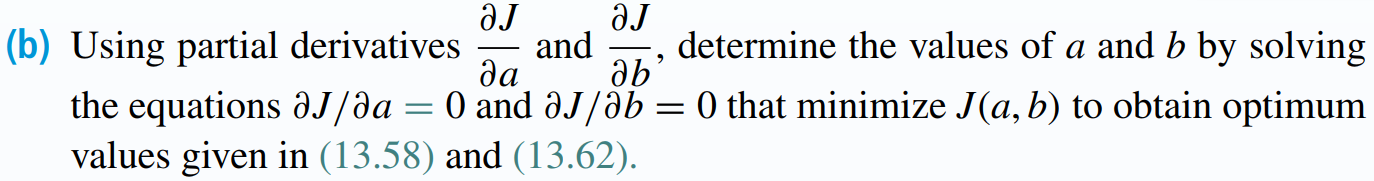

## Problem 13.22: Computing probabilities

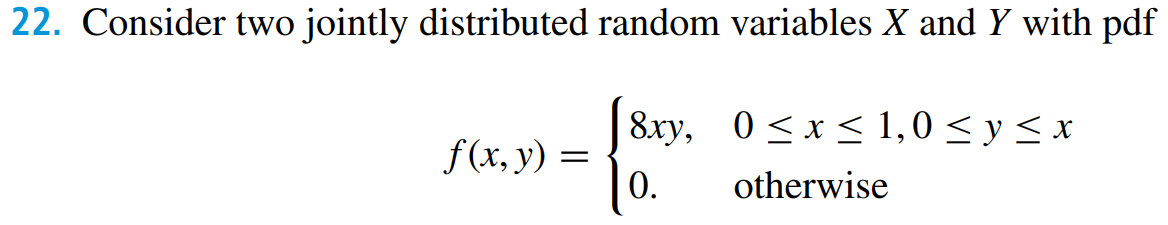

### a) Determine prior and conditional probabilities

### b) Are X and Y independent?